# **IO203 - Digital Loopback**

The IO203 is a digital I/O module providing a total of 64 TTL channels. The transceivers are TTL and CMOS/TTL compatible (5 V/3.3 V, ±24 mA available for 3.3V usage only) and can also be set to be CMOS compliant by on-board jumper. 

Each of the 64 channels can be individually programmed as an input or output. Internally the 64 channels are divided in two groups of 32, and each one is accessed via a single bus access cycle which leads to a simultaneous update of each group with very low latency.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO203 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

### Test Setup

On the terminal board of the TTL digital I/O module, connect the digital output pins to the pins of digital inputs as shown below.

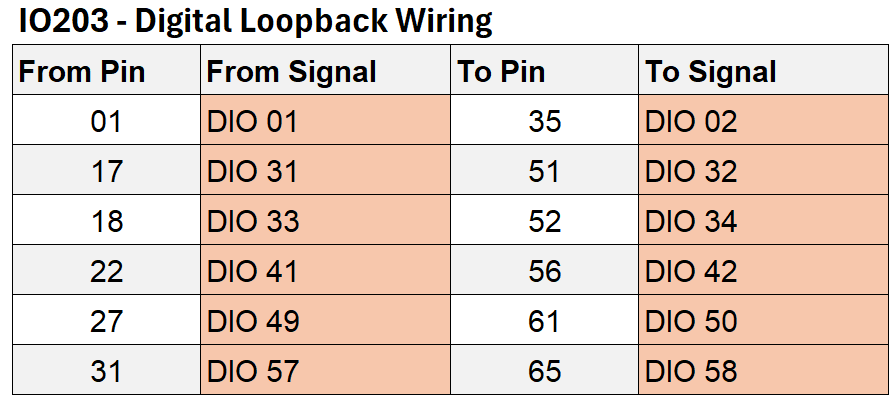

[IO203 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io203_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink Model
modelName = 'sgMdl_IO203_DigitalLoopback';
open_system(modelName);

### Model Description

The Simulink model features the IO203 [Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io203_setup_v2), [Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io203_write_v2) and [Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io203_read_v2) blocks.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
stoptime = 2;
pause(stoptime)
tg.stop;

% Number of signals to be viewed in the SDI
numsignals = 6; 
pause(1)

Simulink.sdi.clearAllSubPlots;
Simulink.sdi.view;
runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:numsignals % Display all signals in the plot
    sigsobj(k).Checked = 1;
end

pause(1)
Simulink.sdi.setSubplotLimits(1, 1, "tMin", 0, "tMax", stoptime, "yMin", -0.5, "yMax", 11.5);

### Check the Results

The output is then visible in the Simulink Data Inspector (SDI). You should see the square waves, like in the image below:

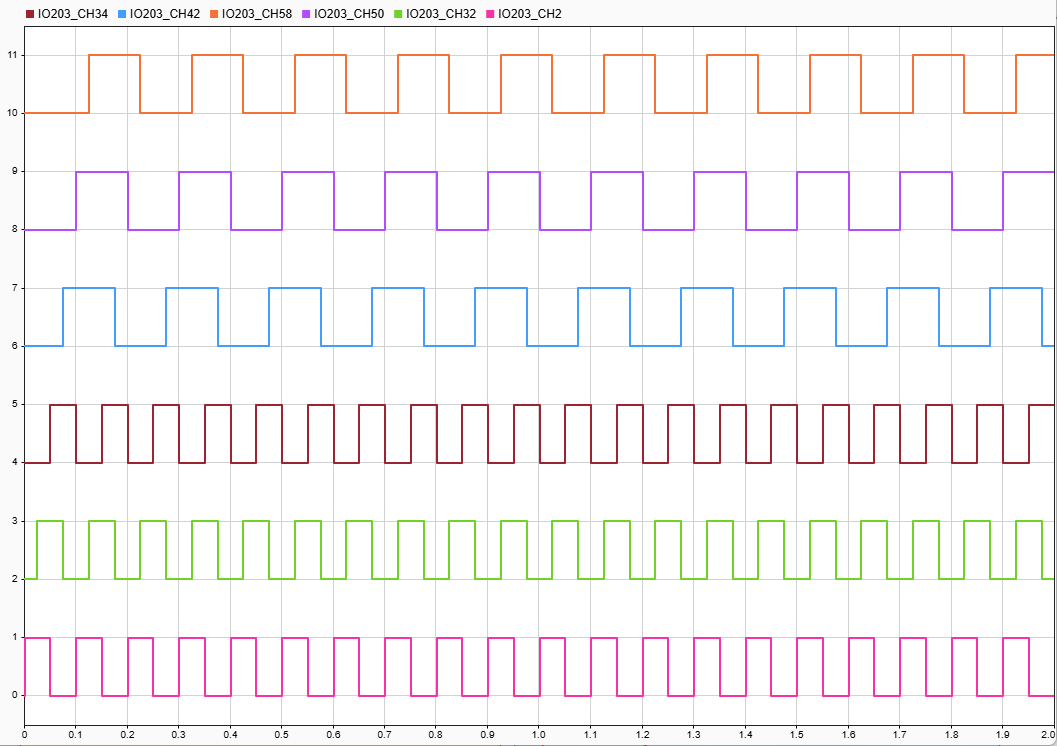

## Additional References

- [IO203 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io203)